
$$\begin{array}{l}
\text{ECSE}\text{ }307-\text{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\text{Professor}\text{ }\text{Aditya}\text{ }\text{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\text{TA}:\text{Mohammad}\text{ }\text{Afshari}\text{ }\text{and}\text{ }\text{Anas}\text{ }\text{El}\text{ }\text{Fathi}
\end{array}$$


# 
$$\text{Lab}\text{ }4$$


# 
$$\mathrm{Controller}\text{ }\mathrm{Design}\text{ }\mathrm{Based}\text{ }\mathrm{on}\text{ }\text{Root}\text{ }\text{Locus}\text{ }\text{of}\text{ }A\text{ }\text{Dynamical}\text{ }\text{System}$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID   = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID   = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, we will use root locus to control the speed of a Coreless DC Motor with a given pre-designed controller and a tunable gain $K$. First, given the pre-designed controller we plot the root locus for the open loop transfer function. Second, using the root locus and a desired step response characteristics, we find the appropriate gain $K$such that the output of the system shows the desired behaviour. Finally, we use the computed gain to drive the motor in order to track a reference angular velocity input.

## **1. Introduction**

Consider the following system. 

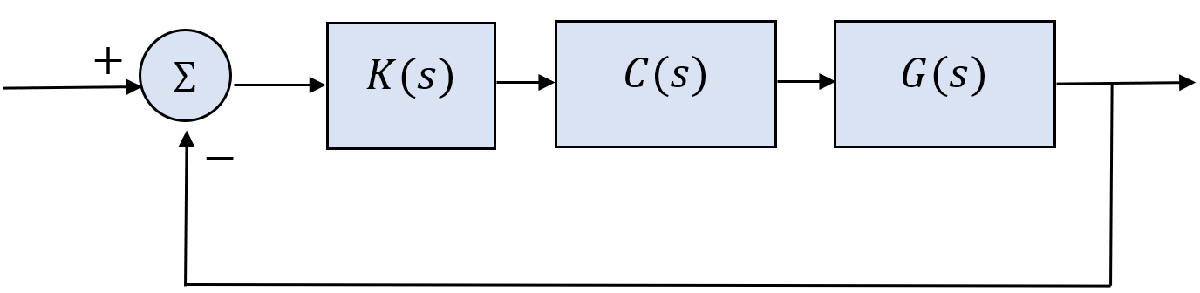

In this system, $G\left(s\right)=\frac{28\ldotp 5}{0\ldotp 14\text{ }s+1}$ is the tranfer function which you identified in Lab03; $C\left(s\right)=\left(1+\frac{21\ldotp 43}{s}\right)$ is our pre-designed PI controller; and $K\left(s\right)=K$ is our tunable gain. 

In the above figure, the open loop and closed loop transfer functions are second order systems. 

***Question 1***

Assume $K=1$, derive the open loop and closed loop transfer functions of the system in MATLAB.

% Place your code here
K = 1;
s = tf('s');
C = 1+(21.43/s)


C =
 
  s + 21.43
  ---------
      s
 
Continuous-time transfer function.



G = 28.5/(0.14*s+1)


G =
 
     28.5
  ----------
  0.14 s + 1
 
Continuous-time transfer function.



% Open loop tf
Ho = K*C*G


Ho =
 
  28.5 s + 610.8
  --------------
   0.14 s^2 + s
 
Continuous-time transfer function.



% Closed loop tf 
Hc = feedback(Ho,1)


Hc =
 
       28.5 s + 610.8
  -------------------------
  0.14 s^2 + 29.5 s + 610.8
 
Continuous-time transfer function.



## ***2.Plot root locus in MATLAB***

In MATLAB, we can use the function `rlocus` to plot the root locus of a system. `rlocus(sys)` calculates and plots the root locus of the open-loop model `sys`**. **To get more information about this function run the followign code:

doc rlocus    % rlocus help

***Question 2***

Using the open loop transfer function you defined in **Question 1**, draw the root locus of the open loop system. Add grids to your plot.

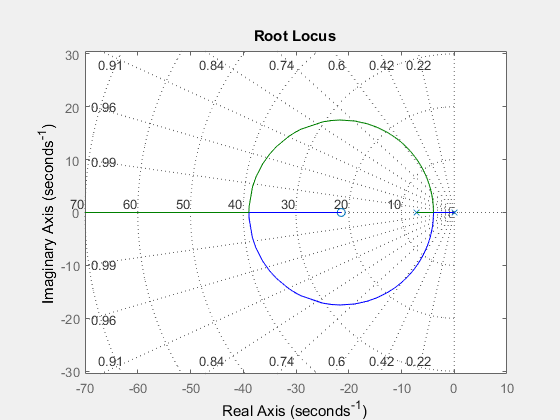

% Place your code here
rlocus(Ho)
set(gcf,'Visible','on')
% set(gcf,'Visible','on') % in adition to your live script, 
%this command plots your result in a new window.

% axis equal % This function set the plot axis with the same distance
axis equal
grid on

## ***3. Controller Design***

The objective of this section is to design a controller $K\left(s\right)$such that the output angular velocity tracks a reference step input with the following specifications:

- Overshoot less than 10%.

- 5% settling time of less than 0.7 seconds.

***Question 3***

In MATLAB, by clicking on each point of the rlocus output plot, you can see the damping ratio ($\xi \text{ }$) and the natural frequency ($\omega_n$) as well as the locations of the poles and the overshoot. 

1. Find the values of the $\xi \text{ }$ and $\omega_n$ from the root locus for which the desired specifications in this **part 3** are satisfied. 

xi = 0.669

xi = 0.6690

w_n = 7.1

w_n = 7.1000

2. What is the gain for which these specifications are satisfied?

K = 0.0116

K = 0.0116

3. based on the values of $\xi \text{ }$and $\omega {\text{ }}_n$ you found in the first part of this question (or the locations of the poles) find the second order characteristic function of the desired system. 

Tdes = w_n^2/(s^2+2*xi*w_n*s+w_n^2)


Tdes =
 
         50.41
  -------------------
  s^2 + 9.5 s + 50.41
 
Continuous-time transfer function.



4. Find the range of the gain for which the overshoot is less than 10%.

*[0, infinity]*

Now we are able to control the DC motor with the value of the gain we found in **Question 3**. let's see how we can control the DC motor with a feedback loop. You have run the DC motor in open loop in Lab03. Now we want to send feedback control actions while the structure is closed loop. Consider the system in the beginning of this Lab with $K=0\ldotp 1$ and $C\left(s\right)=1$. When using the feedback control of the system the input to the system is the error between the reference and the output multiplied by $K$. Below is the code that runs the motor with a feedback. Read, complete, uncomment and run the following code to see how the output speed follows a reference input of 75.

Motor = QnetDCMotor();

K = 0.1;
duration = 5;
dt=0.01;
time = 0:dt:duration;
%%
w_ref = 75;
w_error=zeros(size(time));
w_motor=zeros(size(time));
Motor.reset();
for n=1:length(time)
    t = time(n);             % Define time
    w = Motor.velocity(t);   % Read the speed of the motor
    w_error(n) = w_ref-w;    % Reference - the speed of the motor
    u = w_error(n)*K;        
    Motor.drive(u,t,dt);     % Drives the motor with the given input and time
end

Motor.off();
w_motor=Motor.velocity(0,duration);     % Save motor output in an array
u = Motor.voltage(0,duration);          % Save motor input in an array

**Question 4**

Plot the results for the output and the controller inout (u) of the above exprminet.

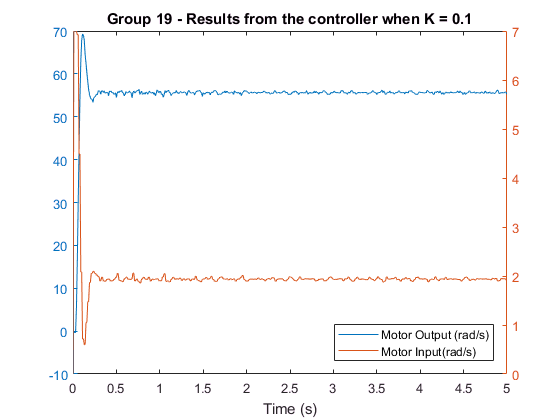

% Plot the results
t = time;
y = w_motor;
v = u;

figure(1)
clf;
yyaxis left
plot(t,y)
yyaxis right 
plot(t,v)
title(sprintf('Group 19 - Results from the controller when K = 0.1'))
xlabel('Time (s)');
legend('Motor Output (rad/s)', 'Motor Input(rad/s)','Location','southeast')

## ***4. Implementing the ******controller***

Now that we have the gain for which the system shows the desired overshoot and settling time and we know how to run and control the motor in feedback control, we can implement the closed loop controlled system and check whether the system has the desired output or not.  

**Question 4**

Using the value of the gain you found in **Question 3 **for $K$ implement the closed loop controlled system given in the beginning of this lab with $C\left(s\right)=\left(1+\frac{21\ldotp 43}{s}\right)$and plot the output with respect to a constant reference input equal to 75 and for 5 seconds. Consider dt to be 0.01.

*Hint 1: Use the following code for your controller input.*

     %u = K*w_error(n)+K*21.43*sum(w_error)*dt;

This is the discrete implementation of the $K\left(1+\frac{21\ldotp 43}{s}\right)$` where sum` returns the sum of array elements. This controller is a PI controller which consists of a proportional part ($K$) and an integral part ($K\frac{\mathrm{21}\ldotp 43}{s}$). 

% Write your codes here
Motor = QnetDCMotor();

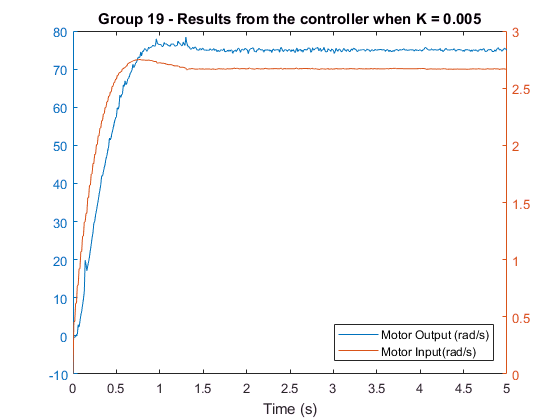

K = 0.005;
duration = 5;
dt=0.01;
time = 0:dt:duration;
w_ref = 75;
w_error=zeros(size(time));
w_motor=zeros(size(time));
Motor.reset();
for n=1:length(time)
    t = time(n);             % Define time
    w = Motor.velocity(t);   % Read the speed of the motor
    w_error(n) = w_ref-w;    % Reference - the speed of the motor
    u = K*w_error(n)+K*21.43*sum(w_error)*dt;      
    Motor.drive(u,t,dt);     % Drives the motor with the given input and time
end
Motor.off();
w_motor=Motor.velocity(0,duration);     % Save motor output in an array
u = Motor.voltage(0,duration);          % Save motor input in an array

% Plot the results

t = time;
y = w_motor;
v = u;

figure(1)
clf;
yyaxis left
plot(t,y)
yyaxis right 
plot(t,v)
title(sprintf('Group 19 - Results from the controller when K = 0.005'))
xlabel('Time (s)');
legend('Motor Output (rad/s)', 'Motor Input(rad/s)','Location','southeast')

***Question 5***

Does your step response show the desired specifications? If not, tweek the values of $K$ till you find a good answer. In your opinion, why tuning is needed?

*No, the step response from our experiment does not show the desired specifications. The desired output of the motor is supposed to be 75. However, the maximum overshoot was greater than 10%. Tuning is needed because it allows us to lower the value of K to 0.005 and thus we were able to get a desired maximum overshoot lower than 10% and a settling time less than 0.7 seconds. *